ESCALÓN RL

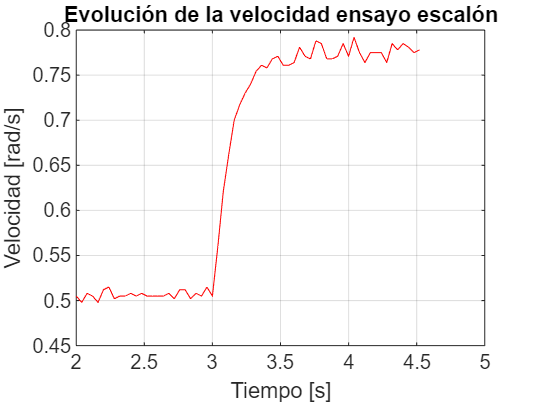

escalon=[
2.000 84 15.540 0.505
2.040 84 15.330 0.498
2.080 84 15.645 0.508
2.120 84 15.540 0.505
2.160 84 15.330 0.498
2.200 84 15.750 0.512
2.240 84 15.855 0.515
2.280 84 15.435 0.502
2.320 84 15.540 0.505
2.360 84 15.540 0.505
2.400 84 15.645 0.508
2.440 84 15.540 0.505
2.480 84 15.645 0.508
2.520 84 15.540 0.505
2.560 84 15.540 0.505
2.600 84 15.540 0.505
2.640 84 15.540 0.505
2.680 84 15.645 0.508
2.720 84 15.435 0.502
2.760 84 15.750 0.512
2.800 84 15.750 0.512
2.840 84 15.435 0.502
2.880 84 15.645 0.508
2.920 84 15.540 0.505
2.960 84 15.855 0.515
3.000 150 15.540 0.505
3.040 150 17.220 0.560
3.080 150 19.109 0.621
3.120 150 20.369 0.662
3.160 150 21.525 0.700
3.200 150 22.049 0.717
3.240 150 22.470 0.730
3.280 150 22.784 0.740
3.320 150 23.204 0.754
3.360 150 23.415 0.761
3.400 150 23.309 0.758
3.440 150 23.624 0.768
3.480 150 23.730 0.771
3.520 150 23.414 0.761
3.560 150 23.414 0.761
3.600 150 23.519 0.764
3.640 150 24.045 0.781
3.680 150 23.730 0.771
3.720 150 23.625 0.768
3.760 150 24.255 0.788
3.800 150 24.150 0.785
3.840 150 23.625 0.768
3.880 150 23.625 0.768
3.920 150 23.730 0.771
3.960 150 24.150 0.785
4.000 150 23.729 0.771
4.040 150 24.360 0.792
4.080 150 23.834 0.775
4.120 150 23.520 0.764
4.160 150 23.834 0.775
4.200 150 23.834 0.775
4.240 150 23.834 0.775
4.280 150 23.520 0.764
4.320 150 24.149 0.785
4.360 150 23.939 0.778
4.400 150 24.149 0.785
4.440 150 24.045 0.781
4.480 150 23.834 0.775
4.520 150 23.939 0.778
];

t = escalon(:,1);
refPWM = escalon(:,2);
u = refPWM - refPWM(1); %Entrada del System Identification
w    = escalon(:,3);
vel = escalon(:,4);
y = vel - vel(1); %Salida del System Identification

figure
plot(t, vel, 'r');
xlabel('Tiempo [s]');
ylabel('Velocidad [rad/s]');
title('Evolución de la velocidad ensayo escalón');
grid on;

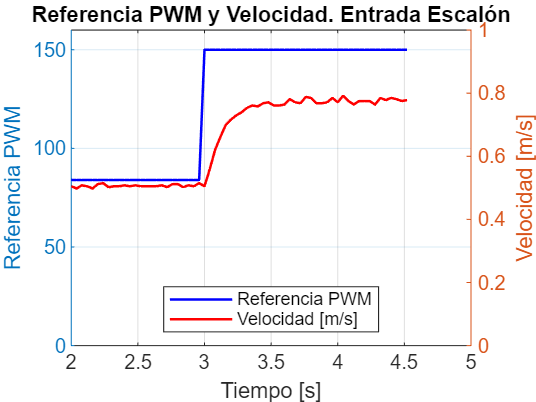


figure;
% Eje izquierdo (referencia PWM)
yyaxis left
p1 = plot(t, refPWM, 'b-', 'LineWidth', 1.2); hold on;
ylim([0 160]);                 % límites del eje izquierdo
ylabel('Referencia PWM');

% Eje derecho (velocidad)
yyaxis right
p2 = plot(t, vel, 'r-', 'LineWidth', 1.2); hold on;
ylim([0 1]);                    % límites del eje derecho
ylabel('Velocidad [m/s]');

xlabel('Tiempo [s]');
title('Referencia PWM y Velocidad. Entrada Escalón');
grid on;

legend({'Referencia PWM','Velocidad [m/s]'}, 'Location','south');

RESPUESTA AL ESCALÓN EN BUCLE ABIERTO

figure
G=tf(tf1) %cargamos nuestro modelo de System Identification


G =
 
  From input "u1" to output "y1":
     0.000805
  ---------------
  1 - 0.8063 z^-1
 
Name: tf1
Sample time: 0.04 seconds
Discrete-time transfer function.
Model Properties


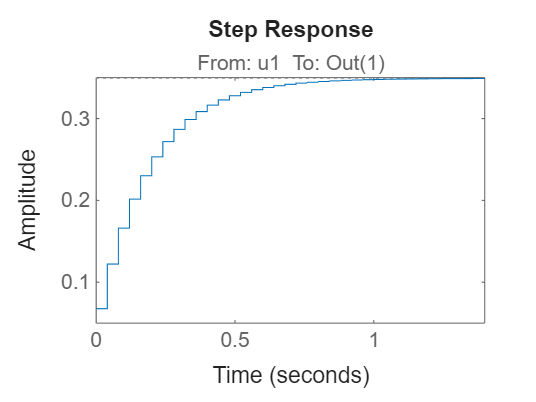

step(84*G) %Vemos la respuesta ante entrada escalón

OBTENCIÓN DE LOS CONTROLADORES PID

figure
%Ajuste manual PID
Kp = 500; Ki = 19000; Kd = 0.0; Ts=0.04;
Cd = pid(Kp, Ki, Kd, 'Ts', Ts)
T = feedback(Cd*G,1);
step(0.386*T)
xlim([0 2]);
grid on

%Hago el controlador con el PID Tuner
%Valores obtenidos con la APP PID Tuner
Kp_tuner = 200.8;
Ki_tuner = 1435;
Kd_tuner = 0;
Ts = 0.04;         

% Crear el controlador discreto
Cd_tuner = pid(Kp_tuner, Ki_tuner, Kd_tuner, 'Ts', Ts)


Cd_tuner =
 
              Ts  
  Kp + Ki * ------
              z-1 

  with Kp = 201, Ki = 1.44e+03, Ts = 0.04
 
Sample time: 0.04 seconds
Discrete-time PI controller in parallel form.
Model Properties


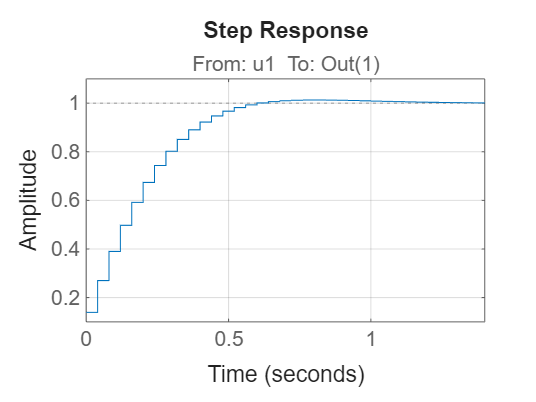

T_tuner=feedback(Cd_tuner*G,1);
step(1*T_tuner)
grid on

Resultados control PID Tuner

escalonPID_Tuner = [

];


t3 = escalonPID_Tuner(:,1);
refvel3 = escalonPID_Tuner(:,2);
refPWM3 = escalonPID_Tuner(:,3);
vel3    = escalonPID_Tuner(:,4);

figure
plot(t3, vel3, 'r');
xlabel('Tiempo [s]');
ylabel('Velocidad [rad/s]');
title('Evolución de la velocidad con ensayo escalón y PID hallado con PID Tuner');
grid on;

figure;
% Eje izquierdo (referencia velocidad rad/s)
yyaxis left
plot(t3, refvel3, 'b-', 'LineWidth', 1.2); hold on;
ylim([0 0.45]);                 % límites del eje izquierdo
ylabel('Referencia rad/s');

% Eje derecho (velocidad)
yyaxis right
plot(t3, vel3, 'r-', 'LineWidth', 1.2); hold on;
ylim([0 0.45]);                    % límites del eje derecho
ylabel('Velocidad [rad/s]');

xlabel('Tiempo [s]');
title('Referencia y Velocidad Angular Entrada Escalón');
grid on;

legend({'Referencia PWM','Velocidad [m/s]'}, 'Location','best');

Resultados control PID Manual

escalonPID_Manual=[
    ];

t4 = escalonPID_Manual(:,1);
refPWM4 = escalonPID_Manual(:,2);
vel4    = escalonPID_Manual(:,3);

figure
plot(t4, vel4, 'r');
xlabel('Tiempo [s]');
ylabel('Velocidad [rad/s]');
title('Ensayo escalón con PID con ajuste manual');
grid on;

figure;
% Eje izquierdo (referencia velocidad rad/s)
yyaxis left
plot(t4, refPWM4, 'b-', 'LineWidth', 1.2); hold on;
ylim([0 25]);                 % límites del eje izquierdo
ylabel('Referencia rad/s');

% Eje derecho (velocidad)
yyaxis right
plot(t4, vel4, 'r-', 'LineWidth', 1.2); hold on;
ylim([0 24]);                    % límites del eje derecho
ylabel('Velocidad [rad/s]');

xlabel('Tiempo [s]');
title('Referencia y Velocidad Angular Entrada Escalón');
grid on;

legend({'Referencia PWM','Velocidad [rad/s]'}, 'Location','best');



